# Module 2: Action Functional Gradient Descent (AFGD) algorithm

clear all
close all

## Load model

lattice_edge = 6; 
model_name = 'Schlogl_1_'+string(lattice_edge)

model_name = "Schlogl_1_6"

plotnam = string(lattice_edge)+"-Schlogl"

plotnam = "6-Schlogl"

model_name = "Selkov"
plotnam = "Selkov"

model_name = "SYN3_FINAL"
plotnam = "12-D Syntrophy model"

model_name = "Cluster_3_catalyst"
plotnam = "3-D Cluster model with catalysis"

model_name = "Cluster_3_catalyst_w_temp"
plotnam = "3-D Cluster model with catalysis & templating"

#### Load ..._Ham.mat from 'data' folder

load('..\Data\'+model_name+'_Ham.mat')

#### Load heteroclinic network

i = row in hc_net. j = column in hc_net - 1 

load('..\Data\' + model_name + '_hcnet.mat')
pos_root_arr

pos_root_arr =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.6838    1.6838    2.0000    2.0000    2.3162    2.3162
    1.6838    1.6838    2.0000    2.3162    2.0000    2.3162
    1.6838    1.6838    2.0000    2.3162    2.3162    2.0000
    1.6838    1.6838    2.3162    2.0000    2.0000    2.3162
    1.6838    1.6838    2.3162    2.0000    2.3162    2.0000
    1.6838    1.6838    2.3162    2.3162    2.0000    2.0000
    1.6838    2.0000    1.6838    2.0000    2.3162    2.3162
    1.6838    2.0000    1.6838    2.3162    2.0000    2.3162
    1.6838    2.0000    1.6838    2.3162    2.3162    2.0000


hc_net

hc_net =    115     1   305
   129   305     1
   135   305     1
   137     1   305
   165     1   305
   171   305     1
   173   305     1
   185     1   305
   187     1   305
   191     1   305


i = 1; j = 1;
sad_pt = i; stab_pt_choice = j;

i = 1; j = 2;
sad_pt = i; stab_pt_choice = j;


#### Load initial condition

Straight 

load('..\Data\' + model_name + '_initcond_'+string(i)...
        +'_'+string(j)+'straight.mat')

Error using load
Unable to read file '..\Data\Schlogl_1_6_initcond_1_1straight.mat'. No such file or directory.

Spiral

load('..\Data\' + model_name + '_initcond_'+string(i)...
+'_'+string(j)+'spiral.mat')
traj_ic = double(traj_ic);

Generate


traj_pt = 2000;
p_o_int = pos_root_arr(hc_net(sad_pt,stab_pt_choice+1),:);
p_o_int = [p_o_int; pos_root_arr(hc_net(sad_pt,1),:)];
t_fin = 1;
t_i = 0 : t_fin/(traj_pt-1) : t_fin;
traj_ic = t_i'*(p_o_int(2,:))+(1-t_i')*(p_o_int(1,:));


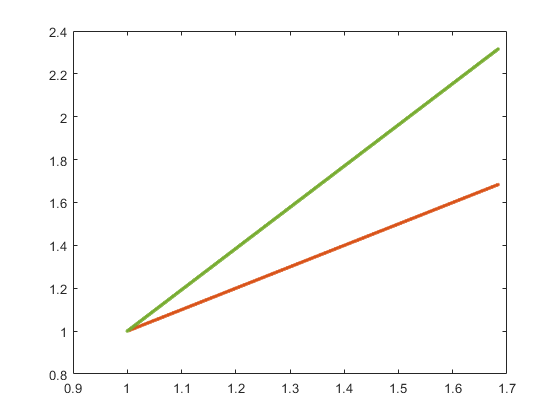

figure()
plot(traj_ic(:,1),traj_ic(:,2:end),'.-')

#### Sample space uniform and plot

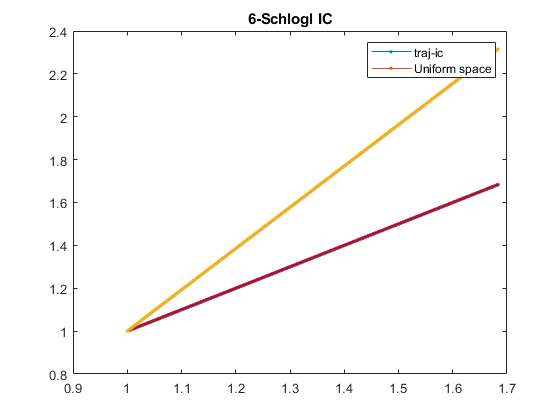

%Space uniform sampling
traj_pts = 2000;
traj_ic = double(traj_ic);
[traj,len_curve_prime] = space_uniform_sampling(traj_ic,traj_pts);
%Plot
figure()
plot(traj_ic(:,1),traj_ic(:,2:end),'.-')
hold on
plot(traj(:,1),traj(:,2:end),'.-')
hold off
legend('traj-ic','Uniform space')
title(plotnam + ' IC')

#### Load from existing data

load("..\Data\Schlogl_1_6_descend_1_1straight_2000_10-Aug-2022.mat")
iter

## Initialize Descender

%number of points in trajectory
traj_pts = size(traj,1)

iter = 210


%Initialize arrays for saving and delta_x_s
Initialize_descender


traj_pts = 2000

%Save data to file in the data folder
savenam = '..\Data\' + model_name + '_descend_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'straight_'+string(traj_pts)+'_'+string(date)+'.mat'

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


S_arr = 0.0769

%Save data to file in the data folder (for spiral)
%savenam = '..\Data\' + model_name + '_descend_'+string(sad_pt)...
%+'_'+string(stab_pt_choice)+'spiral_'+string(traj_pts)+'_'+string(date)+'.mat'

savenam = "..\Data\Schlogl_1_6_descend_1_1straight_2000_10-Aug-2022.mat"

%Save plots 
folder_nam = "Schlogl_6"

folder_nam = "Schlogl_6"

%folder_nam = "Schlogl_2";
%folder_nam = "Selkov";
save_plot_name_root = 'Plots/'+folder_nam+'/'+model_name+'_'+string(sad_pt)...
        +'_'+string(stab_pt_choice)+'_'+string(traj_pts)+'_'+string(date)

save_plot_name_root = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022"


%Plot PS_traj and save
save_plot_name = 'Plots/'+folder_nam+'/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_'+string(traj_pts)+'_'+'_PS_traj_IC.png'

save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000__PS_traj_IC.png"

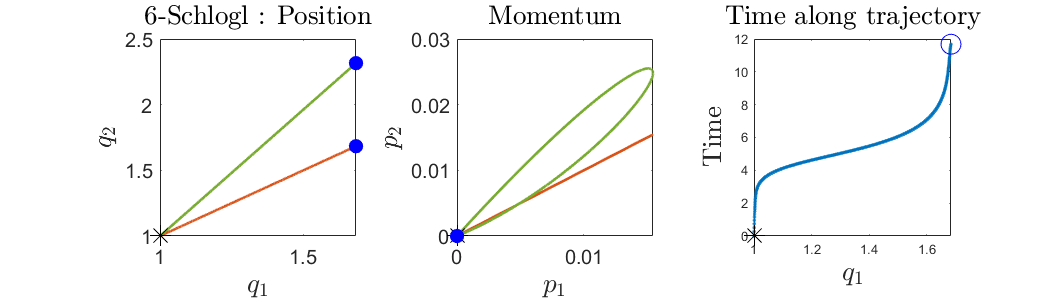

plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,1);


%delta_x_s
delta_x_s =  smooth_traj_butter(delta_x,f0); 

%Plot delta_x and save
save_plot_name = 'Plots/'+folder_nam+'/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_'+string(traj_pts)+'_'+'_deltax_IC.png'

save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000__deltax_IC.png"

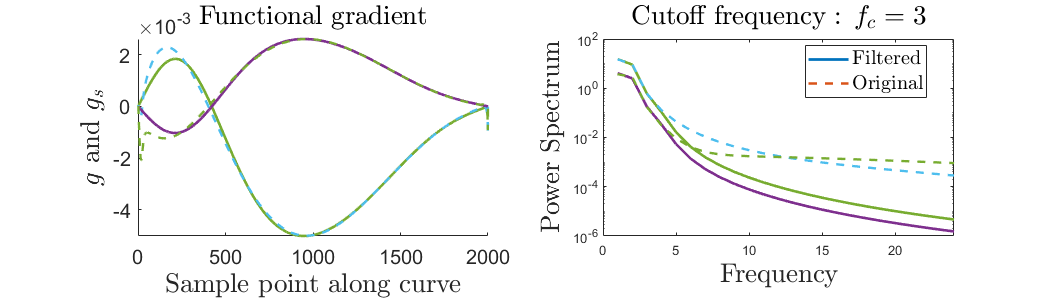

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,1);

## Perform the actual descent

%Actual descender
eps_ic = 1; eps = eps_ic; eps_min = 0.005;     %Initial and least step size
delta_S = 10; err_thresh = 10^(-1); 
f0_max = 40; f0_step = 0.1; f0_init = f0;
eps_S_thresh = 10^(-7); delta_S_thresh = 5*10^(-6);
iter_max = 50; iter = 1; a_min=100; a_thresh = 0.001;
delta_S_thresh_eps = 10^(-7);time_uniform_f = 45;
%time_uniform_f = 35 for Schlogl

f0 = 5; eps_ic = 0.25; eps = eps_ic; eps_min = 0.001; delta_S_thresh = 10^(-9);
delta_S_thresh_eps = 10^(-8);

iter = 30
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
traj = PS_traj(:,1:num_spec);
delta_x_s = picker_arr_idx(deltax_lp_arr,traj_pt_arr,iter);

iter_max = 510;
delta_S_thresh = 5*10^(-7);


format long
anneal_ct = 0;
while f0<f0_max  &&  iter<iter_max && a_min>a_thresh
    iter = iter + 1;
    traj_pts = size(traj,1);

    %take a step in the gradient by picking appropriate step size
    [eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
        (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth,eps_min,delta_S_thresh_eps);
    traj = PS_traj(:,1:num_spec);
    delta_S = action_S_new - action_S;
    [iter, eps, action_S_new, delta_S, f0]
    eps_used = eps;

    

    if abs(delta_S)<delta_S_thresh || eps < eps_min
        f0 = f0 + 0.1; eps = eps_ic; delta_S = 1;  
        traj = time_uniform_filter(traj,t_traj,traj_pts,time_uniform_f);
        [traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
    end

    
    %smoothen gradient for next iteration
    delta_x_s =  smooth_traj_butter(delta_x,f0); 

    %Find closest distance by integrating HamEoM
    a_min = Ham_closest_approach_noplot(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)

    
    %Update descender and save to file
    Update_descender
    save(savenam)
    
    %Plot some stuff in every some iterations
    if mod(iter,10)==0
        save_plot_name = save_plot_name_root +'_deltax_'+string(iter)+'.png'
        debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,1);
        save_plot_name = save_plot_name_root +'_PS_traj_'+string(iter)+'.png'
        plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,1);
        save_plot_name = save_plot_name_root + '_HamEoM_' + string(iter)+'.png';
        a = Ham_closest_approach(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)
    end

    
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


delta_S =     -1.503697809254745e-06


ans = 	1.0e+02 *

   2.110000000000000   0.010000000000000   0.000718989918838  -0.000000015036978   0.030000000000000


a_min =    0.301015936378128


delta_S =     -1.635348035697315e-06


ans = 	1.0e+02 *

   2.120000000000000   0.010000000000000   0.000718973565358  -0.000000016353480   0.030000000000000


a_min =    0.299681175079884


delta_S =     -1.281816576062522e-06


ans = 	1.0e+02 *

   2.130000000000000   0.010000000000000   0.000718960747192  -0.000000012818166   0.030000000000000


a_min =    0.298347530636291


delta_S =     -1.676356504137777e-06


ans = 	1.0e+02 *

   2.140000000000000   0.010000000000000   0.000718943983627  -0.000000016763565   0.030000000000000


a_min =    0.297014520877578


delta_S =     -1.409651554082347e-06


ans = 	1.0e+02 *

   2.150000000000000   0.010000000000000   0.000718929887112  -0.000000014096516   0.030000000000000


a_min =    0.295682275632371


delta_S =     -1.561593527141247e-06


ans = 	1.0e+02 *

   2.160000000000000   0.010000000000000   0.000718914271176  -0.000000015615935   0.030000000000000


a_min =    0.294350317980987


delta_S =     -1.261690394868675e-06


ans = 	1.0e+02 *

   2.170000000000000   0.010000000000000   0.000718901654272  -0.000000012616904   0.030000000000000


a_min =    0.293018664077190


delta_S =     -1.595317365030158e-06


ans = 	1.0e+02 *

   2.180000000000000   0.010000000000000   0.000718885701099  -0.000000015953174   0.030000000000000


a_min =    0.291686870958719


delta_S =     -1.072952933084403e-06


ans = 	1.0e+02 *

   2.190000000000000   0.010000000000000   0.000718874971569  -0.000000010729529   0.030000000000000


a_min =    0.290355217824127


delta_S =     -1.385518452287626e-06


ans = 	1.0e+02 *

   2.200000000000000   0.010000000000000   0.000718861116385  -0.000000013855185   0.030000000000000


a_min =    0.292462152789389


save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_deltax_220.png"

save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_PS_traj_220.png"

a =    0.289022992810220


delta_S =     -1.137609387233396e-06


ans = 	1.0e+02 *

   2.210000000000000   0.010000000000000   0.000718849740291  -0.000000011376094   0.030000000000000


a_min =    0.289682186223504


delta_S =     -1.370259678071251e-06


ans = 	1.0e+02 *

   2.220000000000000   0.010000000000000   0.000718836037694  -0.000000013702597   0.030000000000000


a_min =    0.286927906899492


delta_S =     -1.265154913762667e-06


ans = 	1.0e+02 *

   2.230000000000000   0.010000000000000   0.000718823386145  -0.000000012651549   0.030000000000000


a_min =    0.272996223159236


delta_S =     -1.135164844345837e-06


ans = 	1.0e+02 *

   2.240000000000000   0.010000000000000   0.000718812034497  -0.000000011351648   0.030000000000000


a_min =    0.281568549324839


delta_S =     -1.163869051606925e-06


ans = 	1.0e+02 *

   2.250000000000000   0.010000000000000   0.000718800395806  -0.000000011638691   0.030000000000000


a_min =    0.279002225089655


delta_S =     -1.091983153400644e-06


ans = 	1.0e+02 *

   2.260000000000000   0.010000000000000   0.000718789475975  -0.000000010919832   0.030000000000000


a_min =    0.276542224015773


delta_S =     -1.114399228244189e-06


ans = 	1.0e+02 *

   2.270000000000000   0.010000000000000   0.000718778331982  -0.000000011143992   0.030000000000000


a_min =    0.274223784073745


delta_S =     -1.245245206060730e-06


ans = 	1.0e+02 *

   2.280000000000000   0.010000000000000   0.000718765879530  -0.000000012452452   0.030000000000000


a_min =    0.272083460369639


delta_S =     -1.203839759850167e-06


ans = 	1.0e+02 *

   2.290000000000000   0.010000000000000   0.000718753841133  -0.000000012038398   0.030000000000000


a_min =    0.270159618213694


delta_S =     -9.784561363496147e-07


ans = 	1.0e+02 *

   2.300000000000000   0.010000000000000   0.000718744056571  -0.000000009784561   0.030000000000000


a_min =    0.268472211721131


save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_deltax_230.png"

save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_PS_traj_230.png"

a =    0.268472211721131


delta_S =     -7.508654010640603e-07


ans = 	1.0e+02 *

   2.310000000000000   0.010000000000000   0.000718736547917  -0.000000007508654   0.030000000000000


a_min =    0.267035343533807


delta_S =     -8.246295889607902e-07


ans = 	1.0e+02 *

   2.320000000000000   0.010000000000000   0.000718728301621  -0.000000008246296   0.030000000000000


a_min =    0.265843417220089


delta_S =     -7.746626214943930e-07


ans = 	1.0e+02 *

   2.330000000000000   0.010000000000000   0.000718720554995  -0.000000007746626   0.030000000000000


a_min =    0.262463034175237


delta_S =     -9.427418738577886e-07


ans = 	1.0e+02 *

   2.340000000000000   0.010000000000000   0.000718711127577  -0.000000009427419   0.030000000000000


a_min =    0.258771306975335


delta_S =     -9.340416629588510e-07


ans = 	1.0e+02 *

   2.350000000000000   0.010000000000000   0.000718701787160  -0.000000009340417   0.030000000000000


a_min =    0.254907003386515


delta_S =     -6.490288009530776e-07


ans = 	1.0e+02 *

   2.360000000000000   0.010000000000000   0.000718695296872  -0.000000006490288   0.030000000000000


a_min =    0.250850525321099


delta_S =     -9.561476248393097e-07


ans = 	1.0e+02 *

   2.370000000000000   0.010000000000000   0.000718685735396  -0.000000009561476   0.030000000000000


a_min =    0.246580687924427


delta_S =     -8.967993011255171e-07


ans = 	1.0e+02 *

   2.380000000000000   0.010000000000000   0.000718676767403  -0.000000008967993   0.030000000000000


a_min =    0.242067969066190


delta_S =     -1.073799804837683e-06


ans = 	1.0e+02 *

   2.390000000000000   0.010000000000000   0.000718666029405  -0.000000010737998   0.030000000000000


a_min =    0.237273726951544


delta_S =     -9.534474796901726e-07


ans = 	1.0e+02 *

   2.400000000000000   0.010000000000000   0.000718656494930  -0.000000009534475   0.030000000000000


a_min =    0.232156114986397


save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_deltax_240.png"

save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_PS_traj_240.png"

a =    0.232156114986397


delta_S =     -9.674501009887537e-07


ans = 	1.0e+02 *

   2.410000000000000   0.010000000000000   0.000718646820429  -0.000000009674501   0.030000000000000


a_min =    0.226664957215503


delta_S =     -7.396206015836126e-07


ans = 	1.0e+02 *

   2.420000000000000   0.010000000000000   0.000718639424223  -0.000000007396206   0.030000000000000


a_min =    0.220735313369755


delta_S =     -9.131042290055902e-07


ans = 	1.0e+02 *

   2.430000000000000   0.010000000000000   0.000718630293180  -0.000000009131042   0.030000000000000


a_min =    0.214292240716026


delta_S =     -9.676236506633851e-07


ans = 	1.0e+02 *

   2.440000000000000   0.010000000000000   0.000718620616944  -0.000000009676237   0.030000000000000


a_min =    0.207218991136391


delta_S =     -7.248181062291525e-07


ans = 	1.0e+02 *

   2.450000000000000   0.010000000000000   0.000718613368763  -0.000000007248181   0.030000000000000


a_min =    0.199364559235275


delta_S =     -9.419409519317856e-07


ans = 	1.0e+02 *

   2.460000000000000   0.010000000000000   0.000718603949353  -0.000000009419410   0.030000000000000


a_min =    0.190513748890749


delta_S =     -9.216298849507032e-07


ans = 	1.0e+02 *

   2.470000000000000   0.010000000000000   0.000718594733055  -0.000000009216299   0.030000000000000


a_min =    0.180342189414515


delta_S =     -7.908930139272075e-07


ans = 	1.0e+02 *

   2.480000000000000   0.010000000000000   0.000718586824124  -0.000000007908930   0.030000000000000


a_min =    0.168332213509392


delta_S =     -9.262022088174504e-07


ans = 	1.0e+02 *

   2.490000000000000   0.010000000000000   0.000718577562102  -0.000000009262022   0.030000000000000


a_min =    0.153574835542490


delta_S =     -7.590550376856964e-07


ans = 	1.0e+02 *

   2.500000000000000   0.010000000000000   0.000718569971552  -0.000000007590550   0.030000000000000


a_min =    0.134249647160091


save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_deltax_250.png"

save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_PS_traj_250.png"

a =    0.134249647160091


delta_S =     -7.745675680986830e-07


ans = 	1.0e+02 *

   2.510000000000000   0.010000000000000   0.000718562225876  -0.000000007745676   0.030000000000000


a_min =    0.105763195567939


delta_S =     -7.129464854038758e-07


ans = 	1.0e+02 *

   2.520000000000000   0.010000000000000   0.000718555096411  -0.000000007129465   0.030000000000000


a_min =    0.049655657632693


delta_S =     -7.204227068097202e-07


ans = 	1.0e+02 *

   2.530000000000000   0.010000000000000   0.000718547892184  -0.000000007204227   0.030000000000000


a_min =    0.115340557251743


delta_S =     -8.638714808911763e-07


ans = 	1.0e+02 *

   2.540000000000000   0.010000000000000   0.000718539253469  -0.000000008638715   0.030000000000000


a_min =    0.196214989623102


delta_S =     -9.473270443788318e-07


ans = 	1.0e+02 *

   2.550000000000000   0.010000000000000   0.000718529780199  -0.000000009473270   0.030000000000000


a_min =    0.243601704169228


delta_S =     -7.464797851658433e-07


ans = 	1.0e+02 *

   2.560000000000000   0.010000000000000   0.000718522315401  -0.000000007464798   0.030000000000000


a_min =    0.237138847111873


delta_S =     -7.359695987779746e-07


ans = 	1.0e+02 *

   2.570000000000000   0.010000000000000   0.000718514955705  -0.000000007359696   0.030000000000000


a_min =    0.235498435536667


delta_S =     -7.900544778671748e-07


ans = 	1.0e+02 *

   2.580000000000000   0.010000000000000   0.000718507055160  -0.000000007900545   0.030000000000000


a_min =    0.233838937357766


delta_S =     -7.552903604907124e-07


ans = 	1.0e+02 *

   2.590000000000000   0.010000000000000   0.000718499502257  -0.000000007552904   0.030000000000000


a_min =    0.232159560550139


delta_S =     -6.535665393186951e-07


ans = 	1.0e+02 *

   2.600000000000000   0.010000000000000   0.000718492966591  -0.000000006535665   0.030000000000000


a_min =    0.230458944318513


save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_deltax_260.png"

save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_PS_traj_260.png"

a =    0.230458944318513


delta_S =     -6.925131817575592e-07


ans = 1×5
	1.0e+02 *

   2.610000000000000   0.010000000000000   0.000718486041460  -0.000000006925132   0.030000000000000


a_min =    0.228735753222064


delta_S =     -6.150113100594767e-07


ans = 1×5
	1.0e+02 *

   2.620000000000000   0.010000000000000   0.000718479891347  -0.000000006150113   0.030000000000000


a_min =    0.226989069396903


delta_S =     -7.498812049921977e-07


ans = 1×5
	1.0e+02 *

   2.630000000000000   0.010000000000000   0.000718472392534  -0.000000007498812   0.030000000000000


a_min =    0.225217251538384


delta_S =     -6.828463312985589e-07


ans = 1×5
	1.0e+02 *

   2.640000000000000   0.010000000000000   0.000718465564071  -0.000000006828463   0.030000000000000


a_min =    0.223380522565365


delta_S =     -6.407457963930607e-07


ans = 1×5
	1.0e+02 *

   2.650000000000000   0.010000000000000   0.000718459156613  -0.000000006407458   0.030000000000000


a_min =    0.221468164318606


delta_S =     -7.352877287036819e-07


ans = 1×5
	1.0e+02 *

   2.660000000000000   0.010000000000000   0.000718451803736  -0.000000007352877   0.030000000000000


a_min =    0.219519733263173


delta_S =     -5.950844904345498e-07


ans = 1×5
	1.0e+02 *

   2.670000000000000   0.010000000000000   0.000718445852891  -0.000000005950845   0.030000000000000


a_min =    0.217532970383422


delta_S =     -6.568669030371233e-07


ans = 1×5
	1.0e+02 *

   2.680000000000000   0.010000000000000   0.000718439284222  -0.000000006568669   0.030000000000000


a_min =    0.215489302533855


delta_S =     -7.084672885432353e-07


ans = 1×5
	1.0e+02 *

   2.690000000000000   0.010000000000000   0.000718432199549  -0.000000007084673   0.030000000000000


a_min =    0.213409945408776


delta_S =     -5.435559012750835e-07


ans = 1×5
	1.0e+02 *

   2.700000000000000   0.010000000000000   0.000718426763990  -0.000000005435559   0.030000000000000


a_min =    0.211287192532262


save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_deltax_270.png"

save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_PS_traj_270.png"

a =    0.211287192532262


delta_S =     -7.431876811736515e-07


ans = 1×5
	1.0e+02 *

   2.710000000000000   0.010000000000000   0.000718419332113  -0.000000007431877   0.030000000000000


a_min =    0.209114810737286


delta_S =     -6.145218859332502e-07


ans = 1×5
	1.0e+02 *

   2.720000000000000   0.010000000000000   0.000718413186894  -0.000000006145219   0.030000000000000


a_min =    0.206888348553766


delta_S =     -6.212348145351321e-07


ans = 1×5
	1.0e+02 *

   2.730000000000000   0.010000000000000   0.000718406974546  -0.000000006212348   0.030000000000000


a_min =    0.204601878142037


delta_S =     -5.331813465736523e-07


ans = 1×5
	1.0e+02 *

   2.740000000000000   0.010000000000000   0.000718401642733  -0.000000005331813   0.030000000000000


a_min =    0.202250072552762


delta_S =     -5.695539896516388e-07


ans = 1×5
	1.0e+02 *

   2.750000000000000   0.010000000000000   0.000718395947193  -0.000000005695540   0.030000000000000


a_min =    0.199826391089853


delta_S =     -4.893971766312122e-07


ans = 1×5
	1.0e+02 *

   2.760000000000000   0.010000000000000   0.000718391053221  -0.000000004893972   0.030000000000000


a_min =    0.210166499013898


delta_S =     -1.731841283052205e-05


ans = 1×5
	1.0e+02 *

   2.770000000000000   0.010000000000000   0.000718217869093  -0.000000173184128   0.031000000000000


a_min =    0.201323247557089


delta_S =     -7.679508280261649e-07


ans = 1×5
	1.0e+02 *

   2.780000000000000   0.010000000000000   0.000718210189585  -0.000000007679508   0.031000000000000


a_min =    0.195462472623936


delta_S =     -6.132921798462920e-07


ans = 1×5
	1.0e+02 *

   2.790000000000000   0.010000000000000   0.000718204056663  -0.000000006132922   0.031000000000000


a_min =    0.191396955216062


delta_S =     -4.762790314222221e-07


ans = 1×5
	1.0e+02 *

   2.800000000000000   0.010000000000000   0.000718199293872  -0.000000004762790   0.031000000000000


a_min =    0.207990052628527


save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_deltax_280.png"

save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_PS_traj_280.png"

a =    0.207990052628527


delta_S =     -8.471329786957638e-07


ans = 1×5
	1.0e+02 *

   2.810000000000000   0.010000000000000   0.000718190822543  -0.000000008471330   0.032000000000000


a_min =    0.205536275300440


delta_S =     -5.386624937070428e-07


ans = 1×5
	1.0e+02 *

   2.820000000000000   0.010000000000000   0.000718185435918  -0.000000005386625   0.032000000000000


a_min =    0.203769855225901


delta_S =     -5.765851983224879e-07


ans = 1×5
	1.0e+02 *

   2.830000000000000   0.010000000000000   0.000718179670066  -0.000000005765852   0.032000000000000


a_min =    0.202258505376137


delta_S =     -4.251175710900945e-07


ans = 1×5
	1.0e+02 *

   2.840000000000000   0.010000000000000   0.000718175418890  -0.000000004251176   0.032000000000000


a_min =    0.210642413441416


delta_S =     -7.126614816888033e-07


ans = 1×5
	1.0e+02 *

   2.850000000000000   0.010000000000000   0.000718168292275  -0.000000007126615   0.033000000000000


a_min =    0.208582787431517


delta_S =     -5.981275781330453e-07


ans = 1×5
	1.0e+02 *

   2.860000000000000   0.010000000000000   0.000718162310999  -0.000000005981276   0.033000000000000


a_min =    0.206912975171676


delta_S =     -5.981054249093454e-07


ans = 1×5
	1.0e+02 *

   2.870000000000000   0.010000000000000   0.000718156329945  -0.000000005981054   0.033000000000000


a_min =    0.205341945061451


delta_S =     -6.609778634980579e-07


ans = 1×5
	1.0e+02 *

   2.880000000000000   0.010000000000000   0.000718149720167  -0.000000006609779   0.033000000000000


a_min =    0.203762821359199


delta_S =     -6.142146679877225e-07


ans = 1×5
	1.0e+02 *

   2.890000000000000   0.010000000000000   0.000718143578020  -0.000000006142147   0.033000000000000


a_min =    0.202142044945893


delta_S =     -3.321465312650096e-07


ans = 1×5
	1.0e+02 *

   2.900000000000000   0.010000000000000   0.000718140256555  -0.000000003321465   0.033000000000000


a_min =    0.207814526877645


save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_deltax_290.png"

save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_PS_traj_290.png"

a =    0.207814526877645


delta_S =     -6.410358075054079e-07


ans = 1×5
	1.0e+02 *

   2.910000000000000   0.010000000000000   0.000718133846196  -0.000000006410358   0.034000000000000


a_min =    0.205046813369403


delta_S =     -4.777278793666184e-07


ans = 1×5
	1.0e+02 *

   2.920000000000000   0.010000000000000   0.000718129068918  -0.000000004777279   0.034000000000000


a_min =    0.208405356657729


delta_S =     -7.670286800293136e-07


ans = 1×5
	1.0e+02 *

   2.930000000000000   0.010000000000000   0.000718121398631  -0.000000007670287   0.035000000000000


a_min =    0.205291977964726


delta_S =     -5.639654084843571e-07


ans = 1×5
	1.0e+02 *

   2.940000000000000   0.010000000000000   0.000718115758977  -0.000000005639654   0.035000000000000


a_min =    0.202681728715580


delta_S =     -6.127157407692652e-07


ans = 1×5
	1.0e+02 *

   2.950000000000000   0.010000000000000   0.000718109631819  -0.000000006127157   0.035000000000000


a_min =    0.199822361790378


delta_S =     -5.550127039760655e-07


ans = 1×5
	1.0e+02 *

   2.960000000000000   0.010000000000000   0.000718104081692  -0.000000005550127   0.035000000000000


a_min =    0.197076023666465


delta_S =     -5.478319659302233e-07


ans = 1×5
	1.0e+02 *

   2.970000000000000   0.010000000000000   0.000718098603373  -0.000000005478320   0.035000000000000


a_min =    0.194398111148746


delta_S =     -4.067709396121666e-07


ans = 1×5
	1.0e+02 *

   2.980000000000000   0.010000000000000   0.000718094535663  -0.000000004067709   0.035000000000000


a_min =    0.198435200558423


delta_S =     -6.095619453500012e-07


ans = 1×5
	1.0e+02 *

   2.990000000000000   0.010000000000000   0.000718088440044  -0.000000006095619   0.036000000000000


a_min =    0.194267513306975


delta_S =     -4.151496517390552e-07


ans = 1×5
	1.0e+02 *

   3.000000000000000   0.010000000000000   0.000718084288547  -0.000000004151497   0.036000000000000


a_min =    0.196835305362970


save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_deltax_300.png"

save_plot_name = "Plots/Schlogl_6/Schlogl_1_6_1_1_2000_10-Aug-2022_PS_traj_300.png"

a =    0.196835305362970


delta_S =     -5.907273385175049e-07


ans = 1×5
	1.0e+02 *

   3.010000000000000   0.010000000000000   0.000718078381274  -0.000000005907273   0.037000000000000


a_min =    0.192349348920325


delta_S =     -5.526809676165145e-07


ans = 1×5
	1.0e+02 *

   3.020000000000000   0.010000000000000   0.000718072854464  -0.000000005526810   0.037000000000000


a_min =    0.188599145208995


delta_S =     -6.537836229475458e-07


ans = 1×5
	1.0e+02 *

   3.030000000000000   0.010000000000000   0.000718066316628  -0.000000006537836   0.037000000000000


a_min =    0.184885471720312


delta_S =     -5.544032256471487e-07


ans = 1×5
	1.0e+02 *

   3.040000000000000   0.010000000000000   0.000718060772596  -0.000000005544032   0.037000000000000


a_min =    0.181546178819715


delta_S =     -5.009700131120010e-07


ans = 1×5
	1.0e+02 *

   3.050000000000000   0.010000000000000   0.000718055762896  -0.000000005009700   0.037000000000000


a_min =    0.178493029879056


delta_S =     -3.421000212694425e-07


ans = 1×5
	1.0e+02 *

   3.060000000000000   0.010000000000000   0.000718052341895  -0.000000003421000   0.037000000000000


a_min =    0.183625834065490


delta_S =     -6.545715576788957e-07


ans = 1×5
	1.0e+02 *

   3.070000000000000   0.010000000000000   0.000718045796180  -0.000000006545716   0.038000000000000


a_min =    0.178583878489540


delta_S =     -4.083553043349175e-07


ans = 1×5
	1.0e+02 *

   3.080000000000000   0.010000000000000   0.000718041712627  -0.000000004083553   0.038000000000000


a_min =    0.182232777764097


delta_S =     -6.253812174505935e-07


ans = 1×5
	1.0e+02 *

   3.090000000000000   0.010000000000000   0.000718035458815  -0.000000006253812   0.039000000000000


a_min =    0.177228095532410


format short

format long
S_arr(end)

save_plot_name

        plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,1);


#### Look for a setting which works

format long
f0 = 6; eps_min = 0.001;eps = 0.5;
delta_x_s =  smooth_traj_butter(delta_x,f0); 
debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);
[eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
    (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth,eps_min);
delta_S = action_S_new - action_S;
[iter, eps, action_S_new, delta_S, f0]

traj_pts_new = 3000;
traj = time_uniform_filter(traj,t_traj,traj_pts_new,35);
%[traj,len_curve_prime] = space_uniform_sampling(traj_n_s,traj_pts_new);
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    

f0 = 6; eps_min = 0.03;eps = 0.1;
delta_x_s =  smooth_traj_butter(delta_x,f0); 
[eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
    (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth,eps_min);
delta_S = action_S_new - action_S;
[iter, eps, action_S_new, delta_S, f0]

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

iter = 55;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
S_traj = picker_arr_idx(S_traj_arr,traj_pt_arr,iter);
t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);
save_plot_name = save_plot_name_root + '_' + string(iter) + '_HamEoM';
a = Ham_closest_approach(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)


debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

#### Filter trajectory and see if that reduces a_min

iter = size(S_arr,1)
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
traj = PS_traj(:,1:num_spec);
a_arr_filter = [];

figure()
plot(traj(:,1),traj(:,2))
hold on
for i = 1:12
    traj = time_uniform_filter(traj,t_traj,traj_pts,35);
    [traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
    [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
    a_min = Ham_closest_approach_noplot(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,0,plotnam)
    a_arr_filter = [a_arr_filter; a_min];
    traj = PS_traj(:,1:num_spec);
    plot(traj(:,1),traj(:,2))
end
     hold off

figure()
plot(a_arr_filter)



## Save a trajectory for annealing

iter = 177;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
traj = PS_traj(:,1:num_spec);
traj = time_uniform_filter(traj,t_traj,traj_pts+1500,time_uniform_f);
[traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts+1500);
size(traj)
save('..\Data\Selkov_4000_anneal_traj.mat','traj')

